clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[3.87;-6.69;-7.76];
u31=[0;0;1];
r2=[-7.73;0;0];
u32=[0;0;1];
r3=[3.87;6.69;7.76];
u33=[0;0;1];
r4=[-7.73;0;-11.81];
u34=[0;0;-1];
r5=[3.87;6.69;-4.05];
u35=[0;0;-1];
r6=[3.87;-6.69;3.70];
u36=[0;0;-1];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];

% center and direction of spheroids

hold on
axis([4 15 4 15]);
for R3=5:0.3:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3]; 
end

ans =    10.6000    5.0000    1.0012


ans =     9.8000    5.3000    1.0027


ans =     9.2500    5.6000    1.0040


ans =     8.8500    5.9000    1.0048


ans =     8.5500    6.2000    1.0049


ans =     8.3000    6.5000    1.0071


ans =     8.1500    6.8000    1.0005


ans =     7.9500    7.1000    1.0079


ans =     7.8500    7.4000    1.0024


ans =     7.7500    7.7000    1.0003


ans =     7.6500    8.0000    1.0012


ans =     7.5500    8.3000    1.0050


ans =     7.5000    8.6000    1.0005


ans =     7.4000    8.9000    1.0087


ans =     7.3500    9.2000    1.0077


ans =     7.3000    9.5000    1.0080


ans =     7.2500    9.8000    1.0096


ans =     7.2500   10.1000    1.0004


ans =     7.2000   10.4000    1.0039


ans =     7.1500   10.7000    1.0084


ans =     7.1500   11.0000    1.0013


ans =     7.1000   11.3000    1.0072


ans =     7.1000   11.6000    1.0012


ans =     7.0500   11.9000    1.0083


ans =     7.0500   12.2000    1.0031


ans =     7.0000   12.5000    1.0112


ans =     7.0000   12.8000    1.0068


ans =     7.0000   13.1000    1.0026


ans =     6.9500   13.4000    1.0119


ans =     6.9500   13.7000    1.0083


ans =     6.9500   14.0000    1.0049


ans =     6.9500   14.3000    1.0017


ans =     6.9000   14.6000    1.0122


ans =     6.9000   14.9000    1.0094


scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R1=5:0.3:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     5.0000    5.9000    1.0017


ans =     5.3000    5.9000    1.0017


ans =     5.6000    5.9000    1.0017


ans =     5.9000    5.9000    1.0017


ans =     6.2000    5.9000    1.0017


ans =     6.5000    5.9000    1.0017


ans =     6.8000    5.9000    1.0017


ans =     7.1000    5.9000    1.0017


ans =     7.4000    5.9000    1.0017


ans =     7.7000    5.9000    1.0017


ans =     8.0000    5.9000    1.0017


ans =     8.3000    5.9000    1.0017


ans =     8.6000    5.9000    1.0017


ans =     8.9000    5.9000    1.0017


ans =     9.2000    5.9000    1.0017


ans =     9.5000    5.9000    1.0017


ans = 1×3
    9.8000    5.9000    1.0017


ans = 1×3
   10.1000    5.9000    1.0017


ans = 1×3
   10.4000    5.9000    1.0017


ans = 1×3
   10.7000    5.9000    1.0017


ans = 1×3
   11.0000    5.9000    1.0017


ans = 1×3
   11.3000    5.9000    1.0017


ans = 1×3
   11.6000    5.9000    1.0017


ans = 1×3
   11.9000    5.9000    1.0017


ans = 1×3
   12.2000    5.9000    1.0017


ans = 1×3
   12.5000    5.9000    1.0017


ans = 1×3
   12.8000    5.9000    1.0017


ans = 1×3
   13.1000    5.9000    1.0017


ans = 1×3
   13.4000    5.9000    1.0017


ans = 1×3
   13.7000    5.9000    1.0017


ans = 1×3
   14.0000    5.9000    1.0017


ans = 1×3
   14.3000    5.9000    1.0017


ans = 1×3
   14.6000    5.9000    1.0017


ans = 1×3
   14.9000    5.9000    1.0017


scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','24')

for R1=5:0.3:15 %离心率
    R3=5.6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    5.0000    5.7000    1.0106


ans = 1×3
    5.3000    5.7000    1.0106


ans = 1×3
    5.6000    5.7000    1.0106


ans = 1×3
    5.9000    5.7000    1.0106


ans = 1×3
    6.2000    5.7000    1.0106


ans = 1×3
    6.5000    5.7000    1.0106


ans = 1×3
    6.8000    5.7000    1.0106


ans = 1×3
    7.1000    5.7000    1.0106


ans = 1×3
    7.4000    5.7000    1.0106


ans = 1×3
    7.7000    5.7000    1.0106


ans = 1×3
    8.0000    5.7000    1.0106


ans = 1×3
    8.3000    5.7000    1.0106


ans = 1×3
    8.6000    5.7000    1.0106


ans = 1×3
    8.9000    5.7000    1.0106


ans = 1×3
    9.2000    5.7000    1.0106


ans = 1×3
    9.5000    5.7000    1.0106


ans = 1×3
    9.8000    5.7000    1.0106


ans = 1×3
   10.1000    5.7000    1.0106


ans = 1×3
   10.4000    5.7000    1.0106


ans = 1×3
   10.7000    5.7000    1.0106


ans = 1×3
   11.0000    5.7000    1.0106


ans = 1×3
   11.3000    5.7000    1.0106


ans = 1×3
   11.6000    5.7000    1.0106


ans = 1×3
   11.9000    5.7000    1.0106


ans = 1×3
   12.2000    5.7000    1.0106


ans = 1×3
   12.5000    5.7000    1.0106


ans = 1×3
   12.8000    5.7000    1.0106


ans = 1×3
   13.1000    5.7000    1.0106


ans = 1×3
   13.4000    5.7000    1.0106


ans = 1×3
   13.7000    5.7000    1.0106


ans = 1×3
   14.0000    5.7000    1.0106


ans = 1×3
   14.3000    5.7000    1.0106


ans = 1×3
   14.6000    5.7000    1.0106


ans = 1×3
   14.9000    5.7000    1.0106


scatter(x3,y3,10,'markerfacecolor',[151, 150, 159]/256,...
        'markeredgecolor',[151, 150, 159]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')

for R3=5:0.3:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r5,R1,R3,u32,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r5,R1,R3,u32,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    7.3000    5.0000    1.0053


ans = 1×3
    7.2000    5.3000    1.0107


ans = 1×3
    7.1500    5.6000    1.0077


ans = 1×3
    7.1000    5.9000    1.0071


ans = 1×3
    7.0500    6.2000    1.0086


ans = 1×3
    7.0000    6.5000    1.0119


ans = 1×3
    7.0000    6.8000    1.0036


ans = 1×3
    6.9500    7.1000    1.0094


ans = 1×3
    6.9500    7.4000    1.0030


ans = 1×3
    6.9000    7.7000    1.0108


ans = 1×3
    6.9000    8.0000    1.0057


ans = 1×3
    6.9000    8.3000    1.0011


ans = 1×3
    6.8500    8.6000    1.0108


ans = 1×3
    6.8500    8.9000    1.0072


ans = 1×3
    6.8500    9.2000    1.0038


ans = 1×3
    6.8500    9.5000    1.0008


ans = 1×3
    6.8000    9.8000    1.0122


ans = 1×3
    6.8000   10.1000    1.0097


ans = 1×3
    6.8000   10.4000    1.0074


ans = 1×3
    6.8000   10.7000    1.0053


ans = 1×3
    6.8000   11.0000    1.0034


ans = 1×3
    6.8000   11.3000    1.0016


ans = 1×3
    6.7500   11.6000    1.0144


ans = 1×3
    6.7500   11.9000    1.0129


ans = 1×3
    6.7500   12.2000    1.0115


ans = 1×3
    6.7500   12.5000    1.0101


ans = 1×3
    6.7500   12.8000    1.0089


ans = 1×3
    6.7500   13.1000    1.0078


ans = 1×3
    6.7500   13.4000    1.0067


ans = 1×3
    6.7500   13.7000    1.0057


ans = 1×3
    6.7500   14.0000    1.0048


ans = 1×3
    6.7500   14.3000    1.0040


ans = 1×3
    6.7500   14.6000    1.0031


ans = 1×3
    6.7500   14.9000    1.0024


scatter(x4,y4,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','25')

for R3=5:0.3:15 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r2,r6,R1,R3,u32,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r6,R1,R3,u32,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r6,R1,R3,u32,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    7.2000    5.0000    1.0017


ans = 1×3
    7.1000    5.3000    1.0111


ans = 1×3
    7.0500    5.6000    1.0111


ans = 1×3
    7.0500    5.9000    1.0003


ans = 1×3
    7.0000    6.2000    1.0039


ans = 1×3
    6.9500    6.5000    1.0091


ans = 1×3
    6.9500    6.8000    1.0021


ans = 1×3
    6.9000    7.1000    1.0095


ans = 1×3
    6.9000    7.4000    1.0041


ans = 1×3
    6.8500    7.7000    1.0131


ans = 1×3
    6.8500    8.0000    1.0089


ans = 1×3
    6.8500    8.3000    1.0051


ans = 1×3
    6.8500    8.6000    1.0017


ans = 1×3
    6.8000    8.9000    1.0127


ans = 1×3
    6.8000    9.2000    1.0099


ans = 1×3
    6.8000    9.5000    1.0074


ans = 1×3
    6.8000    9.8000    1.0051


ans = 1×3
    6.8000   10.1000    1.0030


ans = 1×3
    6.8000   10.4000    1.0011


ans = 1×3
    6.7500   10.7000    1.0138


ans = 1×3
    6.7500   11.0000    1.0122


ans = 1×3
    6.7500   11.3000    1.0107


ans = 1×3
    6.7500   11.6000    1.0093


ans = 1×3
    6.7500   11.9000    1.0081


ans = 1×3
    6.7500   12.2000    1.0069


ans = 1×3
    6.7500   12.5000    1.0058


ans = 1×3
    6.7500   12.8000    1.0048


ans = 1×3
    6.7500   13.1000    1.0038


ans = 1×3
    6.7500   13.4000    1.0030


ans = 1×3
    6.7500   13.7000    1.0021


ans = 1×3
    6.7500   14.0000    1.0014


ans = 1×3
    6.7500   14.3000    1.0006


ans = 1×3
    6.7000   14.6000    1.0147


ans = 1×3
    6.7000   14.9000    1.0141


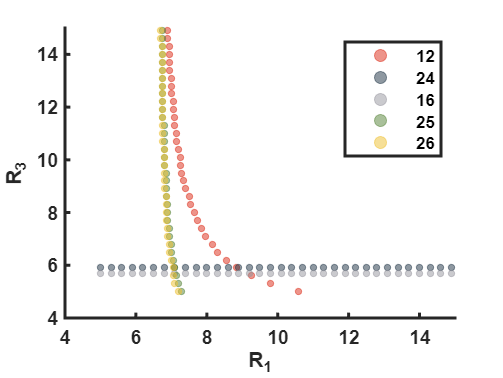

scatter(x5,y5,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','26')

hold off

set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast');

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end



